% cleaning
clc
clear

% importing data
df1=readtable("..\data\experimental-data-1.csv")

df1 = 10×4 table
    dimension    value    uncertainty      uom  
    _________    _____    ___________    _______

     {'d1' }      55          0.5        {'CMT'}
     {'d2' }      60          0.5        {'CMT'}
     {'d3' }      65          0.5        {'CMT'}
     {'d4' }      70          0.5        {'CMT'}
     {'d5' }      75          0.5        {'CMT'}
     {'d6' }      80          0.5        {'CMT'}
     {'d7' }      85          0.5        {'CMT'}
     {'d8' }      90          0.5        {'CMT'}
     {'d9' }      95          0.5        {'CMT'}
     {'d10'}      98          0.5        {'CMT'}


df2=readtable("..\data\experimental-data-2.csv")

df2 = 1000×5 table
    event    distance    time    uncertainty      uom  
    _____    ________    ____    ___________    _______

      1      {'d10'}     819          1         {'C26'}
      2      {'d10'}     799          1         {'C26'}
      3      {'d10'}     818          1         {'C26'}
      4      {'d10'}     819          1         {'C26'}
      5      {'d10'}     815          1         {'C26'}
      6      {'d10'}     817          1         {'C26'}
      7      {'d10'}     818          1         {'C26'}
      8      {'d10'}     798          1         {'C26'}
      9      {'d10'}     819          1         {'C26'}
     10      {'d10'}     819          1         {'C26'}
     11      {'d10'}     819          1         {'C26'}
     12      {'d10'}     817          1         {'C26'}
     13      {'d10'}     8

tools=readtable("..\data\tools.csv")

tools = 2×3 table
                tool                uncertainty      uom  
    ____________________________    ___________    _______

    {'proximity sensor tmd4906'}        0.05       {'SEC'}
    {'graduated rod'           }       0.005       {'MTR'}


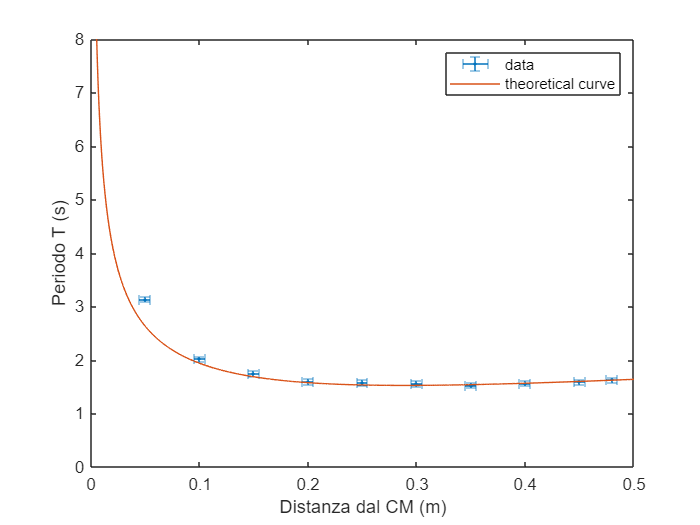


% unique distance
hd=unique(df2.distance);
ld=length(hd);

% defining variable
l0=1;                       % pendulum length
g=9.8;                      % gravitational acceleration
dg=0.1;                     % error gravitational acceleration
dt=tools.uncertainty(1);    % error t
dr=tools.uncertainty(2);    % errror distance

% creating empty array
tm=zeros(ld,1);     % tempi medi
dtm=zeros(ld,1);    % error t
d=zeros(ld,1);      % distance from CM
dd=zeros(ld,1);     % error distance
r=[0:0.0001:0.5];   % theoretical distance
gc=zeros(ld,1);     % gravitational acceleration calculated
dgc=zeros(ld,1);    % error gc
regc=zeros(ld,1);   % relative error gravitational acceleration
cfrg=zeros(ld,1);   % position first significant digit gravitational acceleration
uomd=string(zeros(ld,1));   % uom distance
uomg=string(zeros(ld,1));   % uom g
uomt=string(zeros(ld,1));   % uom t

% multiply *2 and converttng ms2s
for i=1:height(df2)
    df2.time(i)=df2.time(i).*2./1000;
    
    % rounding
    df2.time(i)=round(df2.time(i),2);
end

% core
for i=1:ld
    % calculating mean and converting ms2s
    tm(i)=mean(table2array(df2(df2.distance==string(hd(i)),"time")));
    
    % error t
    % dtm(i)=round(std(table2array(df2(df2.distance==string(hd(i)),"time"))),2);
    dtm(i)=dt;

    % distance from CM
    d(i)=table2array(df1(df1.dimension==string(hd(i)),"value"));
    d(i)=d(i)-50;
    d(i)=d(i)/100; %cm2m
    
    % error distance from CM
    dd(i)=dr;

    % gravitational acceleration
    gc(i)=(l0.^2.*pi.^2)./(3.*d(i).*tm(i).^2)+(4.*pi.^2.*d(i))./(tm(i).^2);
    dgc(i)=((pi.^2).*2.*l0.*dd(i))./(3.*d(i).*tm(i).^2)  +  (((((l0.^2).*pi.^2)/(3.*d(i).*tm(i).^4))+(4.*pi^2.*d(i)./tm(i).^4)).*8.*tm(i).*dtm(i))  +  abs(-((l0.^2.*pi.^2)./(3.*d(i).^2.*tm(i).^2)) + (4.*pi.^2)./(tm(i).^2)).*dd(i);
    
    % propagation of error g
    cfrg(i)=-floor(log10(dgc(i)));  % position first significant digit g
    dgc(i)=round(dgc(i),cfrg(i));   % round dgc
    gc(i)=round(gc(i),cfrg(i)+2);     % round g calculated

    % relative error g
    regc(i)=round(dgc(i)./gc(i)*100,2);
    
    % unit of measure
    uomd(i)="MTR";
    uomg(i)="MSK";
    uomt(i)="SEC";
end

% significant digits time
cfrt=-floor(log10(dt));         % position first significant digit time
tm=round(tm,cfrt);              % round 

% mean gravitational acceleration (output3)
gm=round(mean(gc(2:10)),2);
dgm=round(mean(dgc(2:10)),0);
regm=round((dgm/gm)*100,2);

gm;

% theoretical curve
tt=(2.*pi./sqrt(g)).*sqrt(((l0.^2)./(12.*r))+r);

% plotting
plt=figure;
errorbar(d,tm,dtm,dtm,dd,dd,'.')
xlabel('Distanza dal CM (m)')
ylabel('Periodo T (s)')
xlim([0,0.5])
hold on
plot(r,tt)
hold off
ylim([0,8])
legend('data','theoretical curve')

% converting array to string
d=string(d);
tm=string(tm);
gc=string(gc);
regc=string(regc);

for i=1:ld
    d(i)=sprintf('%.3f',d(i));
    tm(i)=sprintf('%.2f',tm(i));
    gc(i)=sprintf('%.2f',gc(i));
    regc(i)=sprintf('%.2f',regc(i));
end

% significant digit output1
output1=array2table(cat(2,string(hd),d,gc,dgc,regc,uomg),"VariableNames",{'configuration','distance_CM','gravitational_acceleration','uncertainty','relative_error','uom_gravitational_acceleration'});
output1=sortrows(output1,"distance_CM");
output1=output1(:,{'configuration','gravitational_acceleration','uncertainty','relative_error','uom_gravitational_acceleration'}) %remove distance_CM

output1 = 10×5 table
    configuration    gravitational_acceleration    uncertainty    relative_error    uom_gravitational_acceleration
    _____________    __________________________    ___________    ______________    ______________________________

        "d1"                   "6.87"                  "2"           "29.11"                    "MSK"             
        "d2"                   "9.02"                  "2"           "22.17"                    "MSK"             
        "d3"                   "9.09"                  "2"           "22.00"                    "MSK"             
        "d4"                   "9.54"                  "3"           "31.45"                    "MSK"             
        "d5"                   "9.19"                  "2"           "21.76"                    "MSK"             
   


% generating output2
output2=sortrows(array2table(cat(2,string(hd),d,dd,uomd,tm,dtm,uomt),"VariableNames",{'configuration','distance_CM','uncertainty_distance','uom_distance','time','uncertainty_time','uom_time'}),"distance_CM")

output2 = 10×7 table
    configuration    distance_CM    uncertainty_distance    uom_distance     time     uncertainty_time    uom_time
    _____________    ___________    ____________________    ____________    ______    ________________    ________

        "d1"           "0.050"            "0.005"              "MTR"        "3.14"         "0.05"          "SEC"  
        "d2"           "0.100"            "0.005"              "MTR"        "2.02"         "0.05"          "SEC"  
        "d3"           "0.150"            "0.005"              "MTR"        "1.75"         "0.05"          "SEC"  
        "d4"           "0.200"            "0.005"              "MTR"        "1.60"         "0.05"          "SEC"  
        "d5"           "0.250"            "0.005" 

% generating output2
output3=array2table(cat(2,gm,dgm,uomg(1),regm),"VariableNames",{'gravitational_acceleration','uncertainty','uom','relative_error'})

output3 = 1×4 table
    gravitational_acceleration    uncertainty     uom     relative_error
    __________________________    ___________    _____    ______________

              "9.49"                  "2"        "MSK"       "21.07"    


% exporting csv
writetable(output1,'..\data\output-data-1.csv','Delimiter',',','Encoding','UTF-8')
writetable(output2,'..\data\output-data-2.csv','Delimiter',',','Encoding','UTF-8')
writetable(output3,'..\data\output-data-3.csv','Delimiter',',','Encoding','UTF-8')

% exporting img
saveas(plt,'..\img\plot.png');


% exporting mlx2m
mlxloc = fullfile(pwd,'livescript.mlx');
fileout = 'script.m';
matlab.internal.liveeditor.openAndConvert(mlxloc,fileout);